# EQUIVALENT-ELECTRIC-CIRCUIT (EEC) model class

# https://github.com/mhorsche/matlab-eec

% eecmodel = eec(modelstring,'NAME','VALUE');

eecmodel =   eec with properties:

              SpicePath: ''
            ModelString: {'OCV', 'R', 'RC'}

+-------------------------------------------------------------------------------+
|  1. element OCV                                                               |
|                                                                               |
| Voltage of OCV1 [V]: 3.65                                                     |
+-------------------------------------------------------------------------------+
|  2. element R                                                                 |
| continuous: U = R * I                                                         |
|                                                                               |
| Ohmic resistance R2 [Ohm]: 0.035                                              |
+-----------------------------------------------------------

Mögliche Modelparameter:

- OCV: Ruhespannung, meist als konstant Spannungsquelle anzusehen

- R: Rein ohmscher Widerstand

- C: Kondensator

- L: Induktivität

- RC: Parallelschaltung Widerstand || Kondensator

- RL: Parallelschaltung Widerstand || Induktivität

InitialValues definiert die Initialwerte in identischer Reihenfolge wie im Modelstring angegeben.

SpicePath definiert den Pfad zu eurer Spice Executable, beispielsweise:

- Windwos: "C:\Program Files\LTC\LTspiceXVII\XVIIx64.exe"

- MacOS: "/Applications/LTspice.app/Contents/MacOS/LTspice"

## EEC-Objekt erstellen

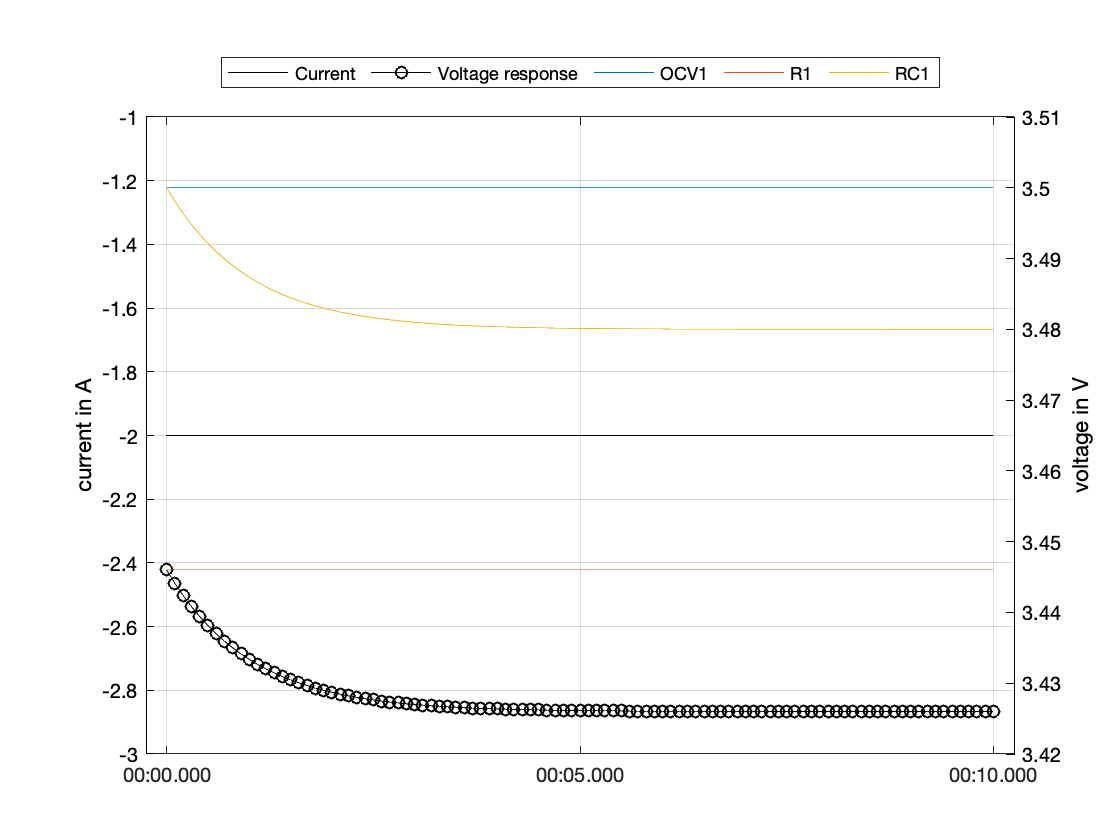

% Einfachers Model aus:
%   1) Ruhespannung
%   2) Widerstand
%   3) RC-Element
eecmodel = eec("OCV+R+RC")

% Manuelles setzten eines einzelnen Elementes
eecmodel.setElementValues('OCV',3.65);

% Direkt beim Erstellen des Objektes die Initialwerte übergeben
OCV = 3.5;
R = 27e-3;
Rrc = 10e-3;
tau = 1;
eecmodel = eec("OCV,R,RC",...
  ...%               Ruhespannung (V) | Widerstandswert (Ohm) | Widerstand RC-Element (Ohm) | Zeitkonstante RC-Element (sec) | Vorladung (As)
    "InitialValues",[      OCV                   R                         Rrc                          tau                         0        ]);

## DC-Analyse: Wie verhält sich das Modell bei einen gegeben Strom

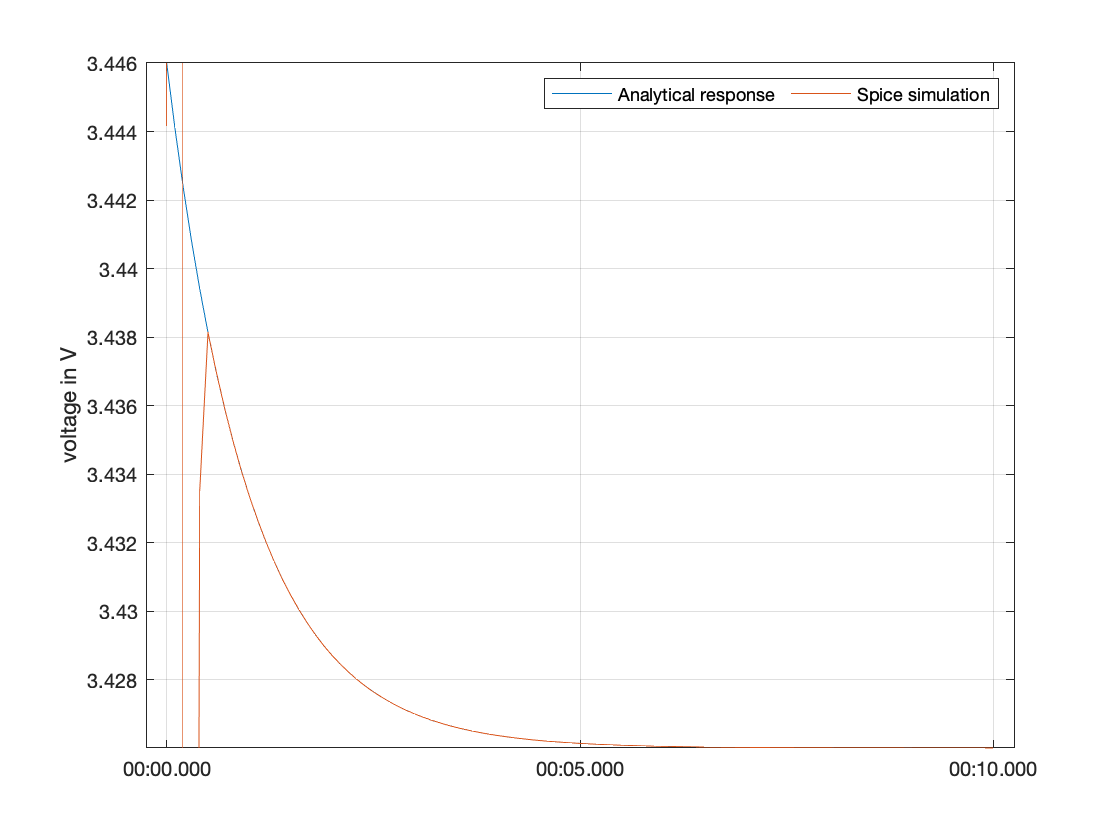

dur = seconds(linspace(0,10,101)); % 10 sec, äquidistant mit 0.1 sec
I = -2.0; % Konstanter Strom von -2.0 Amperer ENTladen

% Einfache Step-Response, Plot wird direkt erstellt
res = eecmodel.dc(dur,I,"doPlot",true);

% Gleiche DC Analyse mit Hilfe des Spice (LTSpice) Solvers
res_spice = eecmodel.spice(dur,I,...
    "MaxStepsize",1e-3,... % dTmax des .tran Befehls
    "UseInitialConditions",false); % .uic Um die Startbedingung zu garantieren

% Alternativ kann der Plot auch nachträglich geöffnet werden
% eecmodel.plotResponse(res_spice);

% Vergleich zwischen Analytical/Spice
figure();
axes();hold on; grid on; box on;

plot(res.t_s,res.Umodel_V);
plot(res_spice.t_s,res_spice.Umodel_V);


xtickformat('mm:ss.SSS');
ylabel('voltage in V');
ylim([min(res.Umodel_V) max(res.Umodel_V)]);

legend('Analytical response','Spice simulation',...
    'Orientation','horizontal');

## Fitting im Zeitbereich: Modell soll bei gegebenen Strom eine bestimmte Spannung liefern

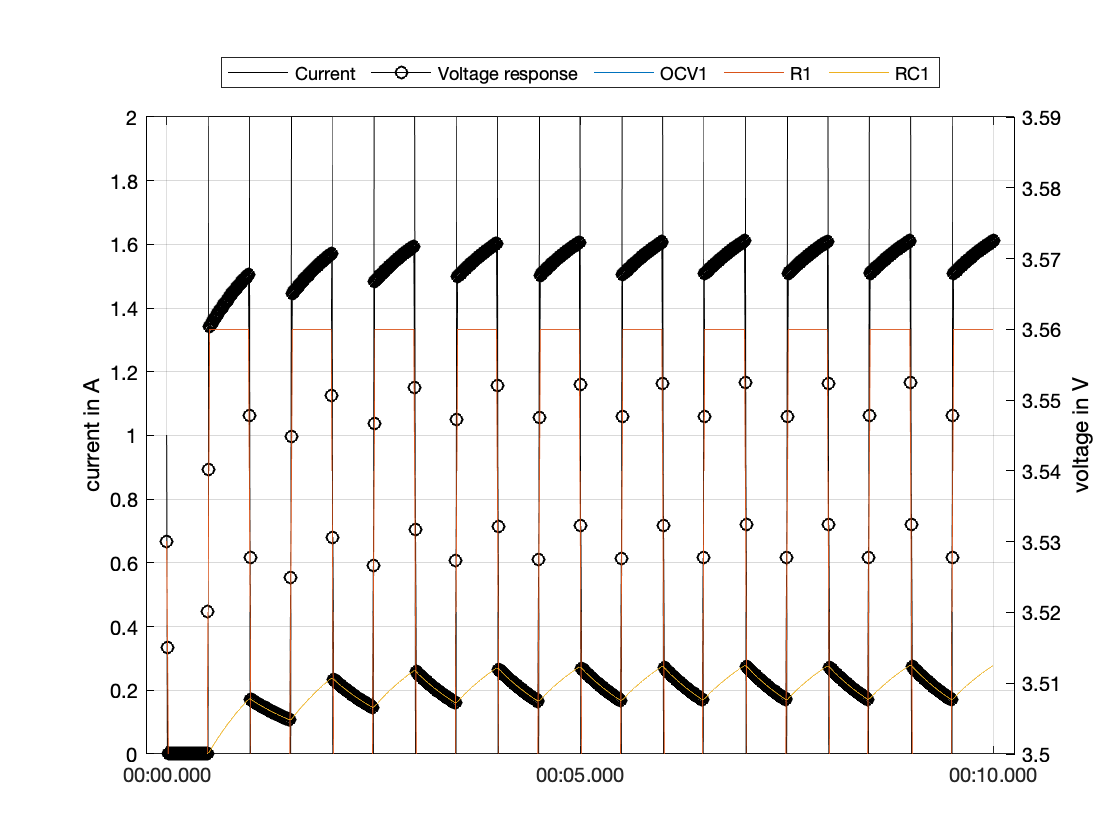

% Zweites Modell erstellen mit veränderten EEC Parametern, das
% ursprüngliche Modell wird dann auf die Spannungsantwort (DC-Analyse) des
% zweiten Modells gefittet, was in den selben Parametern ersichtlich sein
% sollte. Das Zweite Modell wird mit einem Rechtecksignal [0 ... -2] Ampere
% simuliert
eecmodel_new = eec("OCV+R+RC",...
    "InitialValues",[3.5, 30e-3, 10e-3 1 0]); % Widerstand auf 30 mOhm erhöhen, RC Zeitkonstante auf 2 sec erhöhen

% Stromsignal kann natürlich auch ein Zeitlicher Verlauf sein, Time/Current

% müssen dann die gleiche Länge haben, bspw. Rechtecksignal mit 0 bzw. -2 Ampere
dur = seconds(linspace(0,10,1001));
I = -1*sign(sin(2*pi*seconds(dur)))+1;

% Rechtecksignal auf das zweite (veränderte) Modell
res_new = eecmodel_new.dc(dur,I,"doPlot",true);

% Nutze Rechteck zum Fitten
eecmodel.dcfit(res_new.t_s,res_new.I_A,res_new.t_s,res_new.Umodel_V,...


Fitting ('trust-region-reflective') successful after 26 iterations, computation time 0.498923s
Change in x was less than the specified tolerance.

+-------------------------------------------------------------------------------+
|                                     Initial value    Final value       Diff.  |
+-------------------------------------------------------------------------------+
|  1. element OCV                                                               |
|                Voltage of OCV1 [V]:          3.5           3.5 lb     +0.0 %  |
|  2. element R                                                                 |
|          Ohmic resistance R2 [Ohm]:        0.027     0.0291929        +8.1 %  |
|  3. element RC                                                                |
|      Resistor of RC3 element [Ohm]:         0.01          0.01 lb     +0.0 %  |
|   Time constant of RC3 element [s]:         

  "Method","analytical",... % Berechnungsgrundlage jeder Iteration: analytical / spice
  "Display","off",... % Zeige Ergebniss jeder Iteration (optimoptions Option)
  "UseInitials",true,... % Setzte Values auf Initialwerte für erste Iteration
  ...%                     OCV   R      RC1
  "LowerBoundaryRelative",[1     0.8    1 1 NaN],...
  "UpperBoundaryRelative",[1     1.2    1 1 NaN]);

% Ergebnisse im interaktiven Browser darstellen
eecmodel.timeseries(res_new.t_s,res_new.I_A,res_new.t_s,res_new.Umodel_V);

## AC-Analyse: Analyse des Modells mittels Transfer-Funktionen

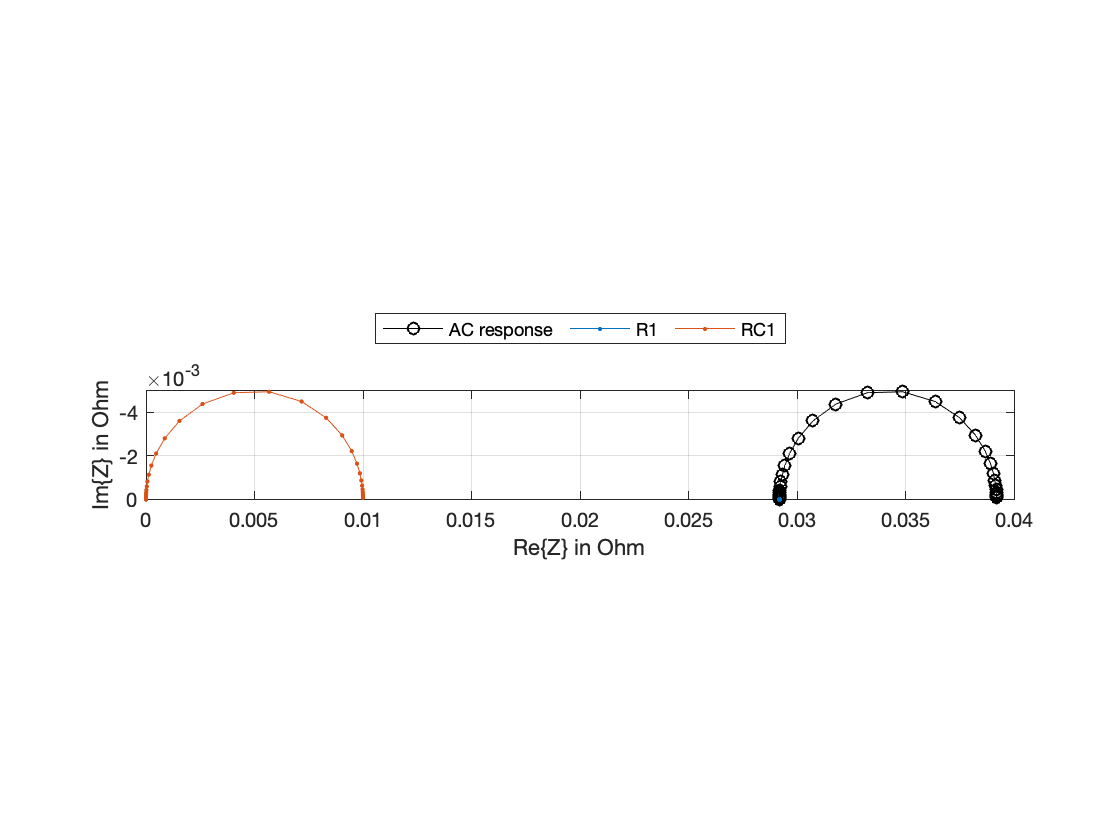

% Logarithmische Verteilung der Frequenzen von 10 kHz ... 1 mHz

f_Hz = logspace(-3,4);

% AC Analyse im definierten Frequenzbereich, das Ergebniss kann wieder
% direkt geplottet werden oder im Nachgang über plotResponse produziert
% werden
res = eecmodel.ac(f_Hz,"doPlot",true);
% eecmodel.plotResponse(res);

## Showcase: Sinus Sweep im DC Bereich, Fitting im AC Bereich

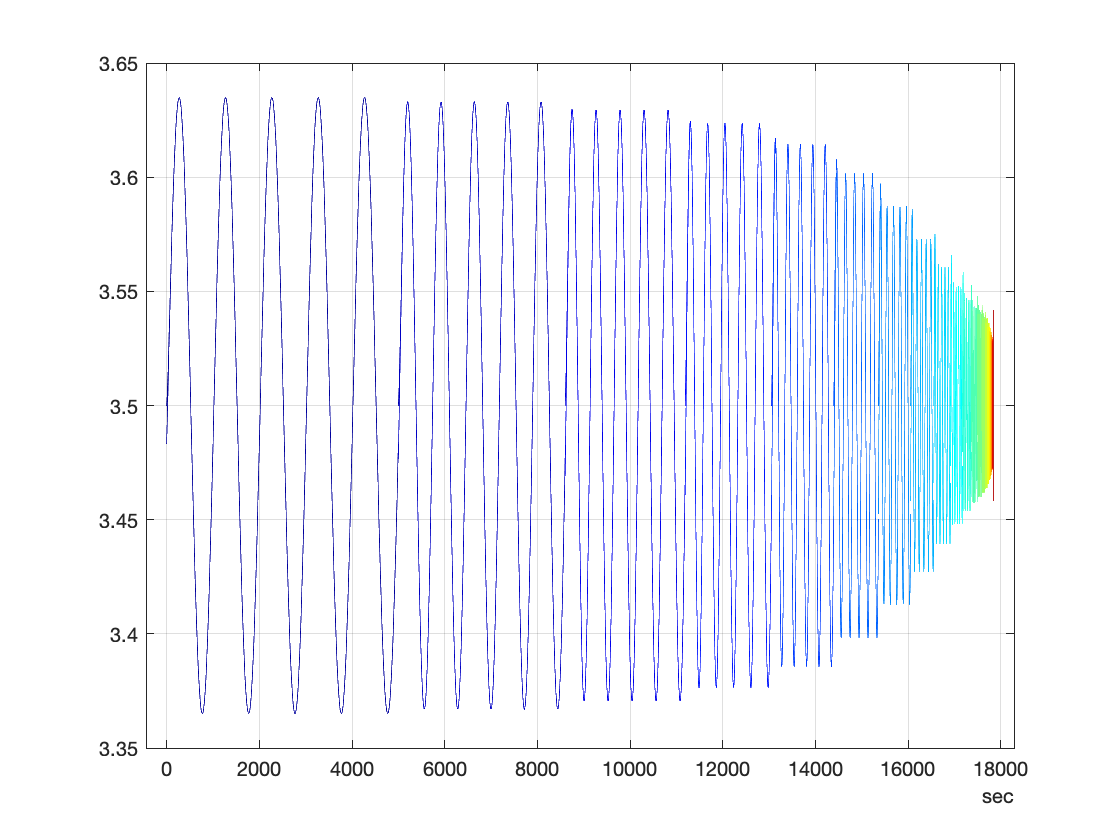

eec_time = eec("OCV+L+R+RC+RC",...
    "InitialValues",[3.5, 500e-9, 27e-3, 10e-3 1 0, 100e-3 30 0]);

f_Hz = logspace(-3,4,50);

% Fit model to data
% sinefct = @(dur,f_Hz,amp,phi)amp*sin(f_Hz*2*pi*seconds(dur) + phi);
ft = fittype( 'a+b*sin(c*x+d)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.TolX = 1e-12;
opts.TolFun = 1e-12;
opts.MaxIter = 1e3;
opts.MaxFunEvals = 20e3;

figure("Name","EEC - Showcase");
ax = axes();hold on; grid on; box on;
ax.ColorOrder = jet(length(f_Hz));

Z = zeros(size(f_Hz)); phi = zeros(size(f_Hz));
toffset_s = seconds(0);
for i = 1:length(f_Hz)
    % Jeweils 5 Perioden mit 1001 Samples
    dur = seconds(linspace(0,5*1/f_Hz(i),1001));
    % Amplitude von 1 (Ampere) und Phaseversatz von 0 Grad, somit 
    % entspricht die Spannungsantwort direkt dem Widerstand
    I = sin(f_Hz(i)*2*pi*seconds(dur));
    
    % DC Response
    res = eec_time.dc(dur,I);
    
    % Spannungsantwort als Sinus fitten, nutze mittleren (eingeschwungenen)
    % Bereich
    opts.Lower =      [3.5   -Inf   2*pi*f_Hz(i)  -Inf];
    opts.StartPoint = [3.5  50e-3   2*pi*f_Hz(i)     0];
    opts.Upper =      [3.5    Inf   2*pi*f_Hz(i)   Inf];
    [fitresult, gof] = fit(seconds(res.t_s(200:800)),res.Umodel_V(200:800),ft,opts);
    
    % Fitting Ergebnis für Amplitude und Phase
    Z(i) = fitresult.b;

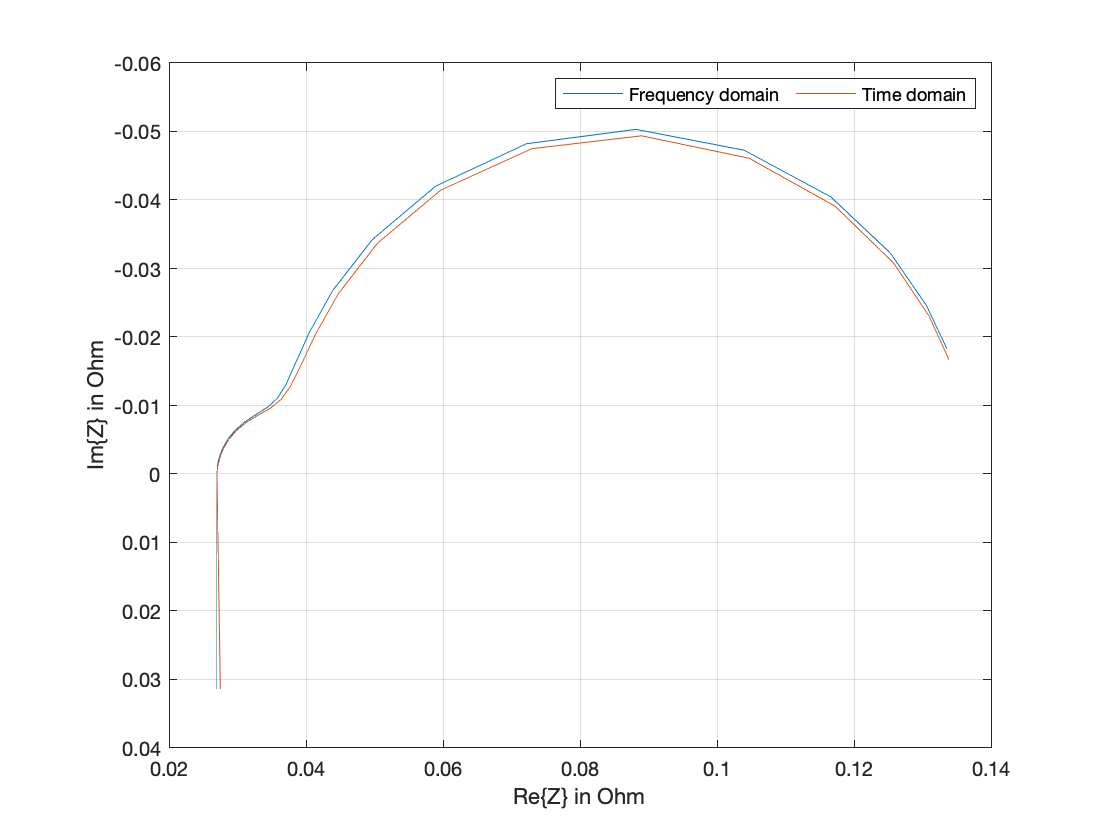

    phi(i) = fitresult.d;
    
    % Zeige Spannungsantwort und Fit als zeitlicher Verlauf
    plot(toffset_s+res.t_s,[res.Umodel_V feval(fitresult,seconds(res.t_s))])
    toffset_s = toffset_s+res.t_s(end);
end
% phi = arctan ( Im / Re );
% Z = sqrt(Re^2 + Im^2);
% Re = Z * cos( phi );
% Im = Z * sin( phi );
ZRe_meas_Ohm = Z .* cos( phi );
ZIm_meas_Ohm = Z .* sin( phi );

% Vergleich zwischen Berechnung im Zeitbereich/Frequenzbereich
res = eec_time.ac(f_Hz);

figure();
ax = axes();hold on; grid on; box on;

pAll(1) = plot(res.ZRe_Ohm,res.ZIm_Ohm);
pAll(2) = plot(ZRe_meas_Ohm,ZIm_meas_Ohm);

xlabel('Re\{Z\} in Ohm')
ylabel('Im\{Z\} in Ohm')
ax.YDir = 'reverse';
ax.DataAspectRatioMode = 'manual';
ax.DataAspectRatio = [1 1 1];

legend('Frequency domain','Time domain',...
    'Orientation','horizontal');


for p1 = pAll
    % adjust DataTip and show frequency for each point
    p1.DataTipTemplate.DataTipRows(1).Label = 'Re\{Z\}';
    p1.DataTipTemplate.DataTipRows(2).Label = 'Im\{Z\}';
    p1.DataTipTemplate.DataTipRows(3) = dataTipTextRow('f in Hz',f_Hz);
end

% Neues Modell welches gefittet werden soll, nutze standard Parameter aus
% Dialog
eec_freq = eec("OCV+L+R+RC+RC");


Fitting ('trust-region-reflective') successful after 415 iterations, computation time 3.576901s
Change in x was less than the specified tolerance.

+-------------------------------------------------------------------------------+
|                                     Initial value    Final value       Diff.  |
+-------------------------------------------------------------------------------+
|  1. element OCV                                                               |
|                Voltage of OCV1 [V]:         3.65          3.65        +0.0 %  |
|  2. element L                                                                 |
|        External Inductivity L2 [H]:      1.5e-08    4.8146e-07     +3109.7 %  |
|  3. element R                                                                 |
|          Ohmic resistance R3 [Ohm]:        0.035     0.0270975       -22.6 %  |
|  4. element RC                     


% Nutze Ergebnisse aus Zeitbereich
eec_freq.acfit(f_Hz,ZRe_meas_Ohm,ZIm_meas_Ohm,...
  "Method","analytical",... % Berechnungsgrundlage jeder Iteration: analytical / spice

Sollwerte:    3.50e+00  5.00e-07  2.70e-02  1.00e-02  1.00e+00  0.00e+00  1.00e-01  3.00e+01  0.00e+00


  "Display","off",... % Zeige Ergebniss jeder Iteration (optimoptions Option)

Istwerte:     3.65e+00  4.81e-07  2.71e-02  1.05e-02  9.81e-01  2.22e-14  9.87e-02  2.94e+01  2.22e-14


  "UseInitials",true); % Setzte Values auf Initialwerte für erste Iteration

Abweichung:    -4.29 %   +3.71 %   -0.36 %   -5.34 %   +1.89 %    -Inf %   +1.27 %   +1.95 %    -Inf %



% Sollwerte [3.5, 500e-9, 27e-3, 10e-3 1 0, 100e-3 30 0], Abweichungen in
% Pozent
fprintf("Sollwerte:  ");fprintf("% 10.2e",[eec_time.Elements.value]);fprintf("\n");
fprintf("Istwerte:   ");fprintf("% 10.2e",[eec_freq.Elements.value]);fprintf("\n");
fprintf("Abweichung: ");fprintf("%+8.2f %%",([eec_time.Elements.value] - [eec_freq.Elements.value]) ./ [eec_time.Elements.value] .* 100);fprintf("\n");

% Ergebnisse im interaktiven Browser darstellen
eec_freq.nyquist(f_Hz,ZRe_meas_Ohm,ZIm_meas_Ohm);